# Editable Text

## Create the widget

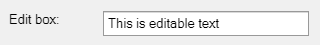

f = figure(...
    'Toolbar','none',...
    'MenuBar','none',...
    'NumberTitle','off',...
    'Units','pixels',...
    'Position',[100 100 320 45]);
movegui(f,[100 -100])

w = uiw.widget.EditableText(...
    'Parent',f,...
    'Value','This is editable text',...
    'Callback',@(h,e)disp(e),...
    'Label','Edit box:',...
    'LabelLocation','left',...
    'LabelWidth',90,...
    'Units','pixels',...
    'Position',[10 10 300 25]);

## Make it a different format

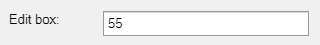

w.FieldType = 'number';
w.Value = 55;


% Set an invalid value, and it won't stick
w.Value = 'abc';

## Show text validity

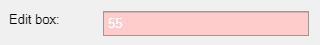

% Toggle this if the user enters an invalid value
w.TextIsValid = false;

## Adjust invalid coloring if desired

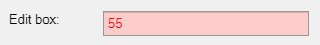

% Invalid text colors
w.TextInvalidBackgroundColor = [1 .8 .8];
w.TextInvalidForegroundColor = [1 0 0];

## Restore text validity

w.TextIsValid = true;